# F21 eksamen

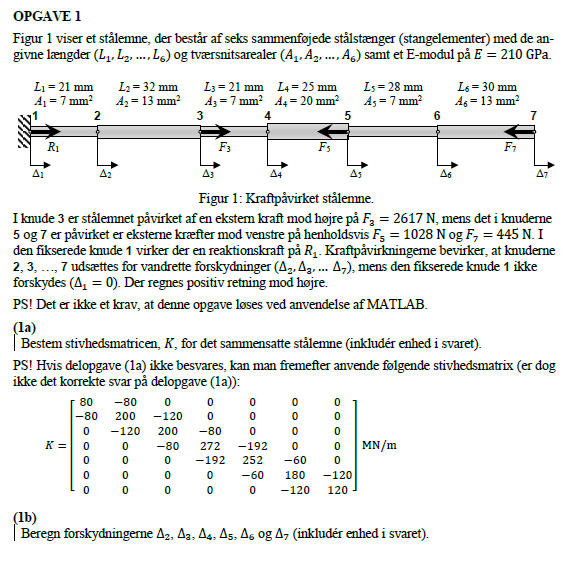

As = [7,13,7,20,7,13]; % mm2
Ls = [21,32,21,25,28,30]; % mm
E = 210; % GPa


n = length(As);

K = zeros(n+1, n+1);
for j = 1:n
    k= As(j)*E/Ls(j);

    Kelm = [k, -k; -k, k];

    K(j:j+1,j:j+1) = K(j:j+1,j:j+1) + Kelm;

end

K

K =    70.0000  -70.0000         0         0         0         0         0
  -70.0000  155.3125  -85.3125         0         0         0         0
         0  -85.3125  155.3125  -70.0000         0         0         0
         0         0  -70.0000  238.0000 -168.0000         0         0
         0         0         0 -168.0000  220.5000  -52.5000         0
         0         0         0         0  -52.5000  143.5000  -91.0000
         0         0         0         0         0  -91.0000   91.0000


Stivhedsmatricen i MN/m

F3 = 2617;
F5 = -1028;
F7 = -445;

n_knuder = 7;

Pfri = [0 F3 0 F5 0 F7]';      % Eksterne kræfter på de frie knuder (N)
Kfri = K(2:n_knuder, 2:n_knuder);  % Del af stivhedsmatrix svarende til frie knuder (N/m). Knude 1 er fast indspændt
D = Kfri\Pfri;              % Forskydninger af de frie knuder (m)
D_my = D';

D_tot = [0 D_my]

D_tot =          0   16.3429   29.7524    8.7095   -0.0583   -8.5345  -13.4246


Forskydninger bliver altså værdierne for knuderne 1-7, i mikrometer

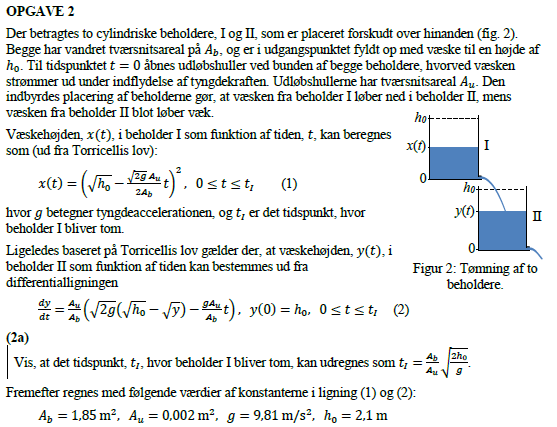

clear

% Der skal løses en ligning
syms h0 g Au Ab t
eq = sqrt(h0) - sqrt(2*g)*Au/(2*Ab)*t == 0;

s = solve(eq, t);

simplify(s)

$$ans = \frac{\sqrt{2}\,\mathrm{Ab}\,\sqrt{h_{0}}}{\mathrm{Au}\,\sqrt{g}}$$

Hvor det fremgår tydeligt at de 2 udtryk er ens

clear

Ab = 1.85; Au = 0.002; g = 9.81; h0 = 2.1;

dydt = @(t,y) Au/Ab * ((sqrt(2*g) * (sqrt(h0) - sqrt(y)) - g*Au/Ab * t))

dydt = function_handle with value:
    @(t,y)Au/Ab*((sqrt(2*g)*(sqrt(h0)-sqrt(y))-g*Au/Ab*t))



y0 = h0; h = 60;

t0 = 0;
t1 = Ab/Au * sqrt(2*h0/g);

span = [t0, t1];

[t,y,iter] = eulode(dydt,span,y0,h);


dy_dt = dydt(t,y);


disp(table(iter, t,y,dy_dt))

    iter      t          y          dy_dt   
    ____    ______    _______    ___________

      0          0        2.1              0
      1         60        2.1    -0.00068792
      2        120     2.0587     -0.0013073
      3        180     1.9803     -0.0018631
      4        240     1.8685      -0.002358
      5        300      1.727     -0.0027932
      6        360     1.5594      -0.003168
      7        420     1.3693     -0.0034797
      8        480     1.1606     -0.0037227
      9        540     0.9372     -0.0038877
     10        600    0.70394     -0.0039575
     11     605.25    0.68318      -0.003958



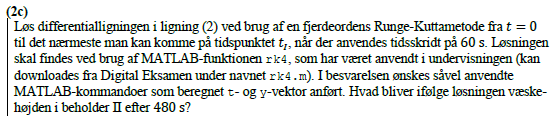

clear
format long
Ab = 1.85; Au = 0.002; g = 9.81; h0 = 2.1;

dydt = @(t,y) Au/Ab * ((sqrt(2*g) * (sqrt(h0) - sqrt(y)) - g*Au/Ab * t))

dydt = function_handle with value:
    @(t,y)Au/Ab*((sqrt(2*g)*(sqrt(h0)-sqrt(y))-g*Au/Ab*t))



y0 = h0; h = 120;

t0 = 0;
t1 = Ab/Au * sqrt(2*h0/g);

span = [t0, t1];

[t,Y, iter] = rk4system(dydt,span,y0,h);

disp(table(iter, t, Y, 'VariableNames',{'iter','Tid [s]', 'Væskehøjde [m]'}))

    iter    Tid [s]     Væskehøjde [m] 
    ____    _______    ________________

     0          0                   2.1
     1        120      2.02266936558235
     2        240      1.81024745668923
     3        360      1.49054207706892
     4        480      1.09176316365475
     5        600      0.64661538391934



Opgave d)

Man ville forvente den var mere præcis, eftersom der er flere skridt for metoden, og man ville forvente en lavere afvigelse med en faktor 2/3, eftersom det er ændringen i skridtet. TJEK MÅSKE VED IKKE OM JEG GIDER

# Funktioner

function [t,y,iter] = eulode(dydt,tspan,y0,h)
% eulode: Euler ODE solver
%   [t,y] = eulode(dydt,tspan,y0,h):
%           uses Euler's method to integrate an ODE
% input:
%   dydt = name of the M-file that evaluates the ODE
%   tspan = [ti, tf] where ti and tf = initial and
%   final values of independent variable
%   y0 = initial value of dependent variable
%   h = step size
% output:
%   t = vector of independent variable
%   y = vector of solution for dependent variable
if nargin<4,error('at least 4 input arguments required'),end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti),error('upper limit must be greater than lower'),end
t = (ti:h:tf)'; n = length(t);
% if necessary, add an additional value of t
% so that range goes from t = ti to tf
if t(n)<tf
    t(n+1) = tf;
    n = n+1;
end
y = y0*ones(n,1); %preallocate y to improve efficiency
iter = [0,];
for i = 1:n-1 %implement Euler's method
    iter(end+1) = i;
    y(i+1) = y(i) + dydt(t(i),y(i))*(t(i+1)-t(i));
end
iter = iter';
end



function [t,Y, iter] = rk4system(dYdt,tspan,Y0,h)
% rk4system: Fourth order Runge-Kutta solver for a system
%            of ODEs
%   [t,Y] = rk4system(dYdt,tspan,Y0,h): uses a fourth 
%     order Runge-Kutta method to solve a system of
%     first order differential equations.
% input:
%   dYdt = a function of (t,Y), where t is the independent
%     variable (scalar) and Y is a row vector of the 
%     dependent variables. The function should return a
%     row vector of derivatives of the independent
%     variables as given by the differential equations.
%   tspan = [ti, tf] where ti and tf = initial and
%     final values of independent variable
%   Y0 = initial value of dependent variables (row
%     vector)
%   h = step size
% output:
%   t = vector with values of the independent variable
%   Y = matrix with solution values of the dependent
%     variables. Each column represents one dependent 
%     variable
ti = tspan(1);
tf = tspan(2);
t = (ti:h:tf)';
n = length(t);
Y(1,:) = Y0;

iter = [0,];
for i = 1:n-1
    iter(end+1) = i;
  k1 = dYdt(t(i),Y(i,:));
  tmid1 = t(i) + h/2;
  Ymid1 = Y(i,:) + k1*h/2;
  k2 = dYdt(tmid1,Ymid1);
  tmid2 = t(i) + h/2;
  Ymid2 = Y(i,:) + k2*h/2;
  k3 = dYdt(tmid2,Ymid2);
  tend = t(i) + h;
  Yend = Y(i,:) + k3*h;
  k4 = dYdt(tend,Yend);
  phi = (k1 + 2*k2 + 2*k3 + k4)/6;
  Y(i+1,:) = Y(i,:) + phi*h;
end
iter = iter';
end






















